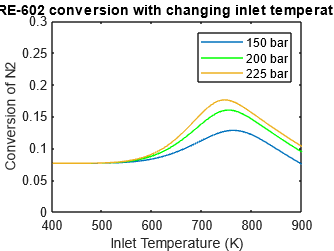

tic

for l = 1:500
    Temp(l) = 400 + l*1;
    T2(1) = Temp(l);
    P(:) = 150 ;

    for  j = 2 : MAXvol2/dV
    
        V2(j) = (j-1)*dV + MAXvol;
        eta2(j-1) = b0+b1*T2(j-1)+b2*X2(j-1)+b3*(T2(j-1)^2)+b4*(X2(j-1)^2)+b5*(T2(j-1)^3)+b6*(X2(j-1)^3);
        fugnh3(j-1) = 0.1438996 +((0.2028538E-2)*T2(j-1))-((0.448762E-3)*P(j-1))-((0.1142945E-5)*T2(j-1)^2)+((0.2761216E-6)*P(j-1));
        fugn2(j-1) =  0.93431737 + ((0.3101804E-3)*T2(j-1)) + ((0.295896E-3)*P(j-1)) - ((0.2707279E-6)*(T2(j-1))^2) + (0.477507E-6*(P(j-1))^2);
        fugh2(j-1) = exp( exp(-3.8402*T2(j-1)^0.125+0.541)*P(j-1) - exp(-0.1263*T2(j-1)^0.5-15.98)*P(j-1)^2 + 300*exp(-0.011901*T2(j-1)-5.941)*exp(P(j-1)/300));
        ynh3_2(j-1) = (YNH3 + 2*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yn2_2(j-1) = (YN2*(1-X2(j-1)))/(1-2*X2(j-1)*YN2);
        yh2_2(j-1) = (YH2 - 3*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yar_2(j-1) = YAr/(1-2*X2(j-1)*YN2);
        yo2_2(j-1) = YO2/(1-2*X2(j-1)*YN2);
        anh3(j-1) = ynh3_2(j-1)*fugnh3(j-1)*P(j-1);
        an2(j-1) = yn2_2(j-1)*fugn2(j-1)*P(j-1);
        ah2(j-1) = yh2_2(j-1)*fugh2(j-1)*P(j-1);
        K2(j-1) = 10^(-2.691122*log10(T2(j-1))-(5.519265*10^(-5))*T2(j-1)+(1.848863*10^(-7))*T2(j-1)^2+(2001.6/T2(j-1))+2.6899);
        Kequil(j-1) = sqrt((anh3(j-1)^2)/(an2(j-1)*ah2(j-1)^3));
        Xequil(j-1) = Kequil(j-1)/(1+Kequil(j-1));
        k2(j-1) = k0*exp(-E2/(R*T2(j-1)));
        Rnh3_2(j-1) = 2*k2(j-1)*(K2(j-1)^2*an2(j-1)*((ah2(j-1)^3)/(anh3(j-1)^2))^alpha-((anh3(j-1)^2)/(ah2(j-1)^3))^(1-alpha)); %kmol/m3.hr
        dHr(j-1) = 4.184*(-(P(j-1))*(0.54526+(840.609)/(T2(j-1))+(459.734E6)/(T2(j-1)^3))-5.34685*T2(j-1)-(0.2525E-3)*T2(j-1)^2+(1.69167E-6)*T2(j-1)^3-9157.09); %kJ/kmol
        CpH2(j-1) = 4.184*(6.952+((-0.04567E-2)*(T2(j-1)))+((0.09563E-5)*(T2(j-1))^2)+((-0.2079E-9)*(T2(j-1))^3));
        CpN2(j-1) = 4.184*(6.903+((-0.03753E-2)*(T2(j-1)))+((0.193E-5)*(T2(j-1))^2)+((-0.6861E-9)*(T2(j-1))^3));
        CpAr(j-1) = 4.184*(4.75);
        CpNH3(j-1) = 4.184*(6.5846 - T2(j-1)*(0.61251E-2) + (T2(j-1)^2)*(0.23663E-5)-(T2(j-1)^3)*(1.5981E-9)+96.1678-0.067571*P(j-1)+T2(j-1)*(-0.2225+(1.6847E-4)*(P(j-1)))+(T2(j-1)^2)*((1.289E-4)-(1.0095E-7)*P(j-1)));
        Cpmix(j-1) = yh2_2(j-1)*CpH2(j-1) + ynh3_2(j-1)*CpNH3(j-1) + yn2_2(j-1)*CpN2(j-1) + yar_2(j-1)*CpAr(j-1);
    
        dXdV = (eta2(j-1) * Rnh3_2(j-1) )/(2*F1N2);
        dTdV = (-(dHr(j-1))*eta2(j-1)*Rnh3_2(j-1))/(F1TOTAL*Cpmix(j-1));
        %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
        X2(j) = X2(j-1) + dXdV*dV;
        T2(j) = T2(j-1) + dTdV*dV;
        %P(i) = P(i-1) + dPdL*dL
    end
    Xout(l) = X2(1,end);
    Tin(l) = T2(1,1);
    Tout1(l) = T2(1,end);
    
end

plot(Tin,Xout)
ylim([0,0.3])
ylabel("Conversion of N2")
xlabel("Inlet Temperature (K)")
title("RE-602 conversion with changing inlet temperature")
hold on


for l = 1:500
    Temp(l) = 400 + l*1;
    T2(1) = Temp(l);
    P(:) = 200;

    for  j = 2 : MAXvol2/dV
    
        V2(j) = (j-1)*dV + MAXvol;
        eta2(j-1) = b0+b1*T2(j-1)+b2*X2(j-1)+b3*(T2(j-1)^2)+b4*(X2(j-1)^2)+b5*(T2(j-1)^3)+b6*(X2(j-1)^3);
        fugnh3(j-1) = 0.1438996 +((0.2028538E-2)*T2(j-1))-((0.448762E-3)*P(j-1))-((0.1142945E-5)*T2(j-1)^2)+((0.2761216E-6)*P(j-1));
        fugn2(j-1) =  0.93431737 + ((0.3101804E-3)*T2(j-1)) + ((0.295896E-3)*P(j-1)) - ((0.2707279E-6)*(T2(j-1))^2) + (0.477507E-6*(P(j-1))^2);
        fugh2(j-1) = exp( exp(-3.8402*T2(j-1)^0.125+0.541)*P(j-1) - exp(-0.1263*T2(j-1)^0.5-15.98)*P(j-1)^2 + 300*exp(-0.011901*T2(j-1)-5.941)*exp(P(j-1)/300));
        ynh3_2(j-1) = (YNH3 + 2*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yn2_2(j-1) = (YN2*(1-X2(j-1)))/(1-2*X2(j-1)*YN2);
        yh2_2(j-1) = (YH2 - 3*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yar_2(j-1) = YAr/(1-2*X2(j-1)*YN2);
        yo2_2(j-1) = YO2/(1-2*X2(j-1)*YN2);
        anh3(j-1) = ynh3_2(j-1)*fugnh3(j-1)*P(j-1);
        an2(j-1) = yn2_2(j-1)*fugn2(j-1)*P(j-1);
        ah2(j-1) = yh2_2(j-1)*fugh2(j-1)*P(j-1);
        K2(j-1) = 10^(-2.691122*log10(T2(j-1))-(5.519265*10^(-5))*T2(j-1)+(1.848863*10^(-7))*T2(j-1)^2+(2001.6/T2(j-1))+2.6899);
        Kequil(j-1) = sqrt((anh3(j-1)^2)/(an2(j-1)*ah2(j-1)^3));
        Xequil(j-1) = Kequil(j-1)/(1+Kequil(j-1));
        k2(j-1) = k0*exp(-E2/(R*T2(j-1)));
        Rnh3_2(j-1) = 2*k2(j-1)*(K2(j-1)^2*an2(j-1)*((ah2(j-1)^3)/(anh3(j-1)^2))^alpha-((anh3(j-1)^2)/(ah2(j-1)^3))^(1-alpha)); %kmol/m3.hr
        dHr(j-1) = 4.184*(-(P(j-1))*(0.54526+(840.609)/(T2(j-1))+(459.734E6)/(T2(j-1)^3))-5.34685*T2(j-1)-(0.2525E-3)*T2(j-1)^2+(1.69167E-6)*T2(j-1)^3-9157.09); %kJ/kmol
        CpH2(j-1) = 4.184*(6.952+((-0.04567E-2)*(T2(j-1)))+((0.09563E-5)*(T2(j-1))^2)+((-0.2079E-9)*(T2(j-1))^3));
        CpN2(j-1) = 4.184*(6.903+((-0.03753E-2)*(T2(j-1)))+((0.193E-5)*(T2(j-1))^2)+((-0.6861E-9)*(T2(j-1))^3));
        CpAr(j-1) = 4.184*(4.75);
        CpNH3(j-1) = 4.184*(6.5846 - T2(j-1)*(0.61251E-2) + (T2(j-1)^2)*(0.23663E-5)-(T2(j-1)^3)*(1.5981E-9)+96.1678-0.067571*P(j-1)+T2(j-1)*(-0.2225+(1.6847E-4)*(P(j-1)))+(T2(j-1)^2)*((1.289E-4)-(1.0095E-7)*P(j-1)));
        Cpmix(j-1) = yh2_2(j-1)*CpH2(j-1) + ynh3_2(j-1)*CpNH3(j-1) + yn2_2(j-1)*CpN2(j-1) + yar_2(j-1)*CpAr(j-1);
    
        dXdV = (eta2(j-1) * Rnh3_2(j-1) )/(2*F1N2);
        dTdV = (-(dHr(j-1))*eta2(j-1)*Rnh3_2(j-1))/(F1TOTAL*Cpmix(j-1));
        %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
        X2(j) = X2(j-1) + dXdV*dV;
        T2(j) = T2(j-1) + dTdV*dV;
        %P(i) = P(i-1) + dPdL*dL
    end
    Xout(l) = X2(1,end);
    Tin(l) = T2(1,1);
    Tout2(l) = T2(1,end);
    
end

plot(Tin,Xout,"green")

for l = 1:500
    Temp(l) = 400 + l*1;
    T2(1) = Temp(l);
    P(:) = 225;

    for  j = 2 : MAXvol2/dV
    
        V2(j) = (j-1)*dV + MAXvol;
        eta2(j-1) = b0+b1*T2(j-1)+b2*X2(j-1)+b3*(T2(j-1)^2)+b4*(X2(j-1)^2)+b5*(T2(j-1)^3)+b6*(X2(j-1)^3);
        fugnh3(j-1) = 0.1438996 +((0.2028538E-2)*T2(j-1))-((0.448762E-3)*P(j-1))-((0.1142945E-5)*T2(j-1)^2)+((0.2761216E-6)*P(j-1));
        fugn2(j-1) =  0.93431737 + ((0.3101804E-3)*T2(j-1)) + ((0.295896E-3)*P(j-1)) - ((0.2707279E-6)*(T2(j-1))^2) + (0.477507E-6*(P(j-1))^2);
        fugh2(j-1) = exp( exp(-3.8402*T2(j-1)^0.125+0.541)*P(j-1) - exp(-0.1263*T2(j-1)^0.5-15.98)*P(j-1)^2 + 300*exp(-0.011901*T2(j-1)-5.941)*exp(P(j-1)/300));
        ynh3_2(j-1) = (YNH3 + 2*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yn2_2(j-1) = (YN2*(1-X2(j-1)))/(1-2*X2(j-1)*YN2);
        yh2_2(j-1) = (YH2 - 3*X2(j-1)*YN2)/(1-2*X2(j-1)*YN2);
        yar_2(j-1) = YAr/(1-2*X2(j-1)*YN2);
        yo2_2(j-1) = YO2/(1-2*X2(j-1)*YN2);
        anh3(j-1) = ynh3_2(j-1)*fugnh3(j-1)*P(j-1);
        an2(j-1) = yn2_2(j-1)*fugn2(j-1)*P(j-1);
        ah2(j-1) = yh2_2(j-1)*fugh2(j-1)*P(j-1);
        K2(j-1) = 10^(-2.691122*log10(T2(j-1))-(5.519265*10^(-5))*T2(j-1)+(1.848863*10^(-7))*T2(j-1)^2+(2001.6/T2(j-1))+2.6899);
        Kequil(j-1) = sqrt((anh3(j-1)^2)/(an2(j-1)*ah2(j-1)^3));
        Xequil(j-1) = Kequil(j-1)/(1+Kequil(j-1));
        k2(j-1) = k0*exp(-E2/(R*T2(j-1)));
        Rnh3_2(j-1) = 2*k2(j-1)*(K2(j-1)^2*an2(j-1)*((ah2(j-1)^3)/(anh3(j-1)^2))^alpha-((anh3(j-1)^2)/(ah2(j-1)^3))^(1-alpha)); %kmol/m3.hr
        dHr(j-1) = 4.184*(-(P(j-1))*(0.54526+(840.609)/(T2(j-1))+(459.734E6)/(T2(j-1)^3))-5.34685*T2(j-1)-(0.2525E-3)*T2(j-1)^2+(1.69167E-6)*T2(j-1)^3-9157.09); %kJ/kmol
        CpH2(j-1) = 4.184*(6.952+((-0.04567E-2)*(T2(j-1)))+((0.09563E-5)*(T2(j-1))^2)+((-0.2079E-9)*(T2(j-1))^3));
        CpN2(j-1) = 4.184*(6.903+((-0.03753E-2)*(T2(j-1)))+((0.193E-5)*(T2(j-1))^2)+((-0.6861E-9)*(T2(j-1))^3));
        CpAr(j-1) = 4.184*(4.75);
        CpNH3(j-1) = 4.184*(6.5846 - T2(j-1)*(0.61251E-2) + (T2(j-1)^2)*(0.23663E-5)-(T2(j-1)^3)*(1.5981E-9)+96.1678-0.067571*P(j-1)+T2(j-1)*(-0.2225+(1.6847E-4)*(P(j-1)))+(T2(j-1)^2)*((1.289E-4)-(1.0095E-7)*P(j-1)));
        Cpmix(j-1) = yh2_2(j-1)*CpH2(j-1) + ynh3_2(j-1)*CpNH3(j-1) + yn2_2(j-1)*CpN2(j-1) + yar_2(j-1)*CpAr(j-1);
    
        dXdV = (eta2(j-1) * Rnh3_2(j-1) )/(2*F1N2);
        dTdV = (-(dHr(j-1))*eta2(j-1)*Rnh3_2(j-1))/(F1TOTAL*Cpmix(j-1));
        %dPdL = (mu*u*150*(1-void)^2)/((void^3)*(dp^2)) - (1.75*rho*(u^2)*(1-void))/((void^3)*(dp))
        X2(j) = X2(j-1) + dXdV*dV;
        T2(j) = T2(j-1) + dTdV*dV;
        %P(i) = P(i-1) + dPdL*dL
    end
    Xout(l) = X2(1,end);
    Tin(l) = T2(1,1);
    Tout3(l) = T2(1,end);
    
end

plot(Tin,Xout)
legend("150 bar","200 bar","225 bar")
hold off

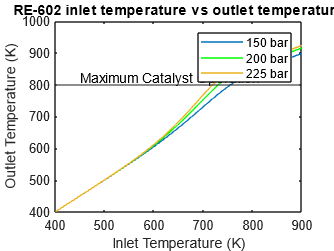


plot(Tin,Tout1)
hold on
plot(Tin,Tout2,"green")
plot(Tin,Tout3)
yline(800)
text(450,825,"Maximum Catalyst Operation")
legend("150 bar","200 bar","225 bar")
ylabel("Outlet Temperature (K)")
xlabel("Inlet Temperature (K)")
title("RE-602 inlet temperature vs outlet temperature")
hold off



toc

Elapsed time is 16.568818 seconds.
